## Sistema de ecuaciones equivalentes con solución única

A = [2 1 -1; 2 -1 1; 6 2 -1]
b = [7 1 16]'
Aa = [A b]
er = rref(Aa)

La solución es única porque *ran(A) = ran(Aa) = número de variables = 3*

## Sistema de ecuaciones sin solución

A = [2 1 -1; 2 -1 1; 6 2 -2]
b = [7 1 2]'
Aa = [A b]
er = rref(Aa)

El sistema no tiene solución porque *ran(A) = 2 ~= ran(Aa) = 3.*

## Sistema de ecuaciones con infinitas soluciones

A = [2 1 -1; 2 -1 1; 6 3 -3]
b=[7 1 21]'
Aa=[A b]
rref(Aa)

## Resolviendo un sistema de ecuaciones con parametros

syms m real
A = [2 1 -1; 1 -2 1; 5 -5 2]
b = [1 3 m]'
Aa = [A b]
Aa(3, :) = Aa(3, :) - 5 * Aa(2, :)

## Ejemplo - Flujo de tráfico

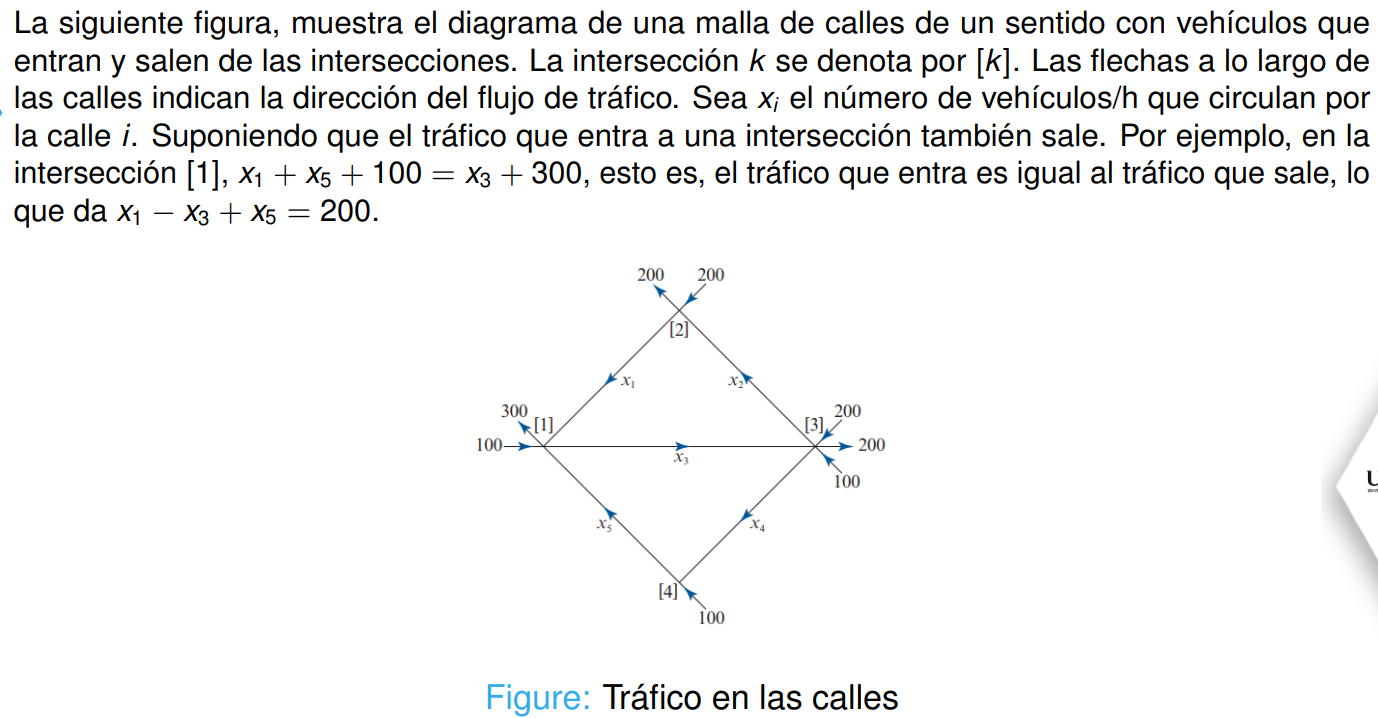

A = [1 0 -1 0 1; 1 -1 0 0 0; 0 1 -1 1 0; 0 0 0 -1 1]

A =      1     0    -1     0     1
     1    -1     0     0     0
     0     1    -1     1     0
     0     0     0    -1     1


b = [200 0 100 100]'

b =    200
     0
   100
   100


Aa = [A b]

Aa =      1     0    -1     0     1   200
     1    -1     0     0     0     0
     0     1    -1     1     0   100
     0     0     0    -1     1   100


er = rref(Aa)

er =      1     0    -1     0     1   200
     0     1    -1     0     1   200
     0     0     0     1    -1  -100
     0     0     0     0     0     0


RoucheFrobenius(A, b)

El sistema tiene infinitas soluciones 
 

Existen infinitas soluciones porque *ran(A) = ran(Aa) < número de variables.*

**NOTA: **Las variables libres son aquellas que no están en la posición de los *pivots.*